This script generates likelihood of transitioning to peer-occupied arms across sessions-days for each genotypic pair across cohorts. Also, it generates mean likelihood of transitioning to peer-occupied arms for all cohorts. **Slight modifications might be needed for plotting purposes (depending if the user is interested in generating data for a particular cohort or all cohorts.

**Input: **Parent data structure containing data for all 6 cohorts


cd 'H:\Social W Behavioral Data\Cohort-6\Results' % change directory to where .mat file is ("parent" data structure)
load 'Cohorts1_6-March-17-2023.mat' % parent data structure with data from all 6 cohorts 

    
  
GroupPrefix={'20','XFB','XFE','XFG','XFJ','XFK','ER1'}; % cohort names (N=6)
genotypetable=table([1 4; 1 2; 2 3; 3 4; 2 4; 1 3;3 4],... % genotypes for each cohort e.g., rat 1 & rat 4 of cohort 1 ("20") are Wt.  
    [2 3; 3 4; 1 4; 1 2; 1 3;2 4;1 2],...
    'VariableNames',{'controls','fx'});

load 'H:\Social W Behavioral Data\Cohort-ER1\Results\Cohort ER1.mat'

cohortER1

cohortER1 = 144×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum
    cohortname
    cohortnum
    runum
    ratnums
    ratnames
    ratsamples
    tries
    matches
    wins
    nTransitions
    genopair
    duration


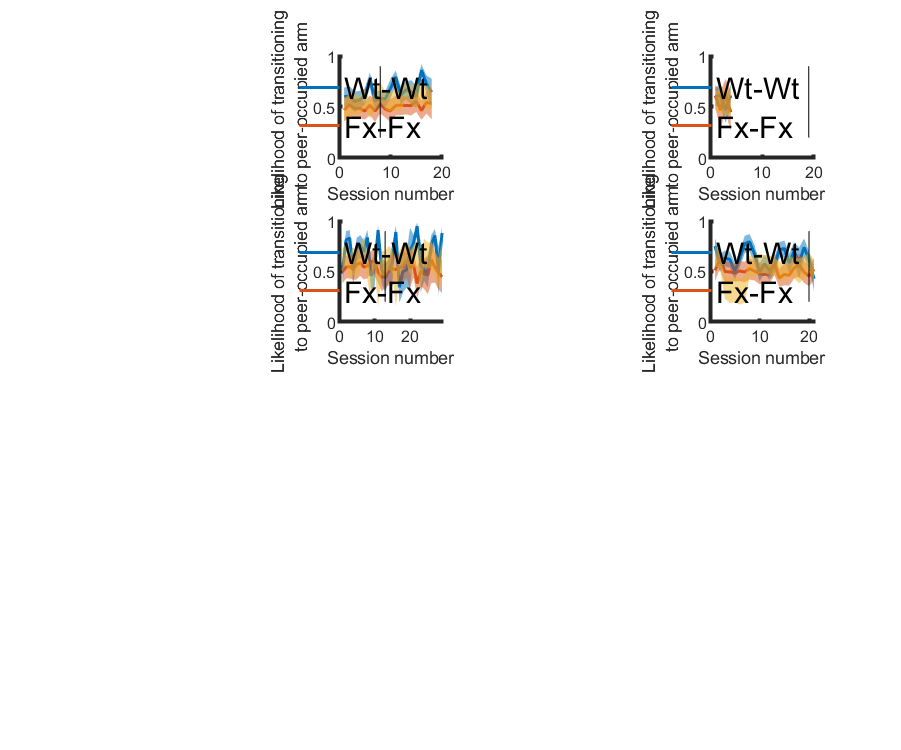




% deblind here:
%{
cohort 1 (20x) 1 and 4 are controls
cohort 2 (XFB) 1 and 2 are controls
cohort 3 (XFE) 1 and 4 are controls
cohort 4 (XFG) 3 and 4 are controls
cohort 5 (XFJ) 2 and 4 are controls
cohort 6 (XFK) 1 and 3 are controls
%}
%critsess=[12 8 14 7 14 15]; % criterion performance sessions

figure;
allcohorts=[]; rundates=[];
iterator=1;
%cohort=6;
for cohort=7 % iterate across cohorts
    cohortinfo=cohort1_6(cell2mat({cohort1_6.cohortnum})==cohort); % extract cohort-specific data
    
    % first quantify number of arm visits per animal
    firsthit=[]; fxpair=[]; combos=[];
    
    varnames={'perfA','perfB','totA','totB','teamPerf','totRewards'};
    ctrlsraw=table([],[],[],[],[],[],'VariableNames',varnames); % Wt-Wt pair
    fxpairraw=ctrlsraw; % Fx-Fx pair
    combosraw=table([],[],[],[],[],[],'VariableNames',varnames); % Wt-Fx pairs
    
    % get unique days, so you can get a day average
    mydates=cellfun(@(a) datenum(a,'dd-mm-yy'), {cohortinfo.date}); % get list of unique days
    addhalf=cellfun(@(a) a>6, {cohortinfo.runum}); % add half to those days containing >6 runs (double runs)
    mydates(addhalf)=mydates(addhalf)+.5; % add half to those days 
    [sessnums,ia,ic]=unique(mydates); % get unique days and associated indexes
  
    for i=1:length(sessnums) % iterate across unique days
        daysess=cohortinfo(ic==i); % extract day-specific sessions
        daysess(cellfun(@(a) a==1,{daysess.opaqueControl}))=[]; % exclude opaqueControl sessions
        cumct=1; % iterator
        if ~isempty(daysess) && length(unique([daysess.genopair]))==3 % if day contains representation of all genotypes (if all genopairs ran/data is available)
            % for each day you want an average of wt wt, wt fx, and fx fx for
            % wins, candidates and the ratio of the two..
            % end matrix will be a m day by 5 by n sess/day matrix
            for k=1:length(daysess) % iterate across sessions within a given unique day
                % controls (no fx?) only one sess
                if ~any(intersect(genotypetable.fx(cohort,:),daysess(k).ratnums)) % if is a Wt-Wt pair (cross-reference with genotype table)
                    % quantify # arm transitions for each rat
                    for rt=1:2 % iterate across rats
                        % my last well ~= my current well and my last well ~=
                        % his current well (please refer to ratsamples ledger on
                        % the parent data structure)
                         candidates=daysess(k).ratsamples{rt}.thiswell~=daysess(k).ratsamples{rt}.lastwell & ...
                             daysess(k).ratsamples{rt}.hiswell~=daysess(k).ratsamples{rt}.lastwell; % if rat transitions and is not coming from peer's well
                        
                        
                        
                        % my last well ~= my current well and my current well
                        % == his current well
                        wins=daysess(k).ratsamples{rt}.thiswell~=daysess(k).ratsamples{rt}.lastwell & ...
                            daysess(k).ratsamples{rt}.hiswell==daysess(k).ratsamples{rt}.thiswell; % match
                        % % of candidates are wins
                        
                        ctrlsraw{i,rt}=sum(wins)/sum(candidates); % succesful trials/trials
                        ctrlsraw{i,rt+2}=sum(candidates); % total trials
                        
                    end
                    % rews / tot trans
                    ctrlsraw{i,5}=sum(ctrlsraw{i,1}*ctrlsraw{i,3}+ctrlsraw{i,2}*ctrlsraw{i,4})/...
                        sum(ctrlsraw{i,3:4}); % get matches per total moves
                    ctrlsraw{i,6}=sum(daysess(k).ratsamples{rt}.Reward)/sum(ctrlsraw{i,3:4}); % get Rewards per total moves
                    
                    
                    % fx only
                elseif ~any(intersect(genotypetable.controls(cohort,:),daysess(k).ratnums)) % if is a Fx-Fx pair
                    % quantify # arm transitions for each rat
                    for rt=1:2
                        % my last well ~= my current well and my last well ~=
                        % his current well
                        candidates=daysess(k).ratsamples{rt}.thiswell~=daysess(k).ratsamples{rt}.lastwell & ...
                            daysess(k).ratsamples{rt}.hiswell~=daysess(k).ratsamples{rt}.lastwell;
                        % my last well ~= my current well and my current well
                        % == his current well
                        
                       
                        
                        wins=daysess(k).ratsamples{rt}.thiswell~=daysess(k).ratsamples{rt}.lastwell & ...
                            daysess(k).ratsamples{rt}.hiswell==daysess(k).ratsamples{rt}.thiswell;
                        % % of candidates are wins
                        fxpairraw{i,rt}=sum(wins)/sum(candidates); % get performance rate
                        fxpairraw{i,rt+2}=sum(candidates); % get total moves
                    end
                    % rews / tot trans
                    fxpairraw{i,5}=(fxpairraw{i,1}*fxpairraw{i,3}+fxpairraw{i,2}*fxpairraw{i,4})/...
                        sum(fxpairraw{i,3:4}); % get matches per total moves
                    fxpairraw{i,6}=sum(daysess(k).ratsamples{rt}.Reward)/sum(fxpairraw{i,3:4}); % get rewards per total moves
                    
                else % if is a Wt-Fx pair
                    for rt=1:2
                        % my last well ~= my current well and my last well ~=
                        % his current well
                        candidates=daysess(k).ratsamples{rt}.thiswell~=daysess(k).ratsamples{rt}.lastwell & ...
                            daysess(k).ratsamples{rt}.hiswell~=daysess(k).ratsamples{rt}.lastwell;
                        % my last well ~= my current well and my current well
                        % == his current well
                        
                       
                        
                        wins=daysess(k).ratsamples{rt}.thiswell~=daysess(k).ratsamples{rt}.lastwell & ...
                            daysess(k).ratsamples{rt}.hiswell==daysess(k).ratsamples{rt}.thiswell;
                        % % of candidates are wins
                        combosraw.(varnames{rt})(i,cumct)=sum(wins)/sum(candidates); % get performance rate
                        combosraw.(varnames{rt+2})(i,cumct)=sum(candidates); % get total moves
                    end
                    % rews / tot trans
                    combosraw.teamPerf(i,cumct)=(combosraw.(varnames{1})(i,cumct)*combosraw.(varnames{3})(i,cumct)+...
                        combosraw.(varnames{2})(i,cumct)*combosraw.(varnames{4})(i,cumct))/...
                        sum(combosraw{i,3}(cumct)+combosraw{i,4}(cumct)); % get matches per total moves
                    combosraw.totRewards(i,cumct)=sum(daysess(k).ratsamples{rt}.Reward)/(combosraw{i,3}(cumct)+combosraw{i,4}(cumct)); % get rewards per total moves
                    
                    cumct=cumct+1;
                end
            end
        end
    end
    
    myvars=combosraw.Properties.VariableNames; % extract variable names
    combomeans=table; % generate table
    for i=1:length(myvars) % iterate across variables
        combomeans.(myvars{i})=mean(combosraw.(myvars{i}),2); % add means
    end
    
    missingdays=combomeans.teamPerf==0 | fxpairraw.teamPerf==0 |...
        ctrlsraw.teamPerf==0; % itentify missing days (no reward)
    combomeans(missingdays,:)=[]; % remove those
    fxpairraw(missingdays,:)=[]; % same
    ctrlsraw(missingdays,:)=[]; % same
    
    barcolors=lines(3); % colors
    % a paired bar graph
    minheight=min([height(ctrlsraw) height(combomeans) height(fxpairraw)]); % how many elements 
    meanvals=[mean(ctrlsraw{critsess(cohort):minheight,1:2},2) mean(combomeans{critsess(cohort):minheight,1:2},2) mean(fxpairraw{critsess(cohort):minheight,1:2},2)]-0.5; % calculate mean across sessions(days) from crit performance day onward only
    
    allcohorts=[allcohorts; meanvals]; % stack cohort-specific data 
    iterator=iterator+1;


    subplot(4,4,iterator);
    % arm transitions go to friends arm
   
    % lets fit these data to a binomial probability distribution
    % binofit (wins tots, p0)
    [ctrlsraw.binomean, ctrlsraw.binoBounds] = binofit(ctrlsraw.perfA.*ctrlsraw.totA+ctrlsraw.perfB.*ctrlsraw.totB,...
        ctrlsraw.totA+ctrlsraw.totB,0.05);
    [fxpairraw.binomean, fxpairraw.binoBounds] = binofit(fxpairraw.perfA.*fxpairraw.totA+fxpairraw.perfB.*fxpairraw.totB,...
        fxpairraw.totA+fxpairraw.totB,0.05);
    % combos is more complicated
    [combomeans.binomean, combomeans.binoBounds] = binofit(round(combomeans.perfA.*combomeans.totA+combomeans.perfB.*combomeans.totB),...
        round(combomeans.totA+combomeans.totB),0.05);
    
    critperfs=[[ctrlsraw.binoBounds(:,1)] [combomeans.binoBounds(:,1)] [fxpairraw.binoBounds(:,1)]];
    critperfs(:,:,2)=[critperfs(2:end,:); nan nan nan];
    critdays=sum(critperfs>.5,3)==2;
    critsess(cohort)=find(any(critdays==1 ,2),1,'first');
   
    

   plot(ctrlsraw.binomean(critsess(cohort):end),'linewidth',1.5); hold on; plot(fxpairraw.binomean(critsess(cohort):end),'linewidth',1.5); %plot(mean(combomeans.binomean(critsess(cohort):end),3));
 
    mycolors=lines(3);
   
    patch([1:size(ctrlsraw(critsess(cohort):end,:),1) size(ctrlsraw(critsess(cohort):end,:),1):-1:1]',[ctrlsraw.binoBounds(critsess(cohort):end,1)' flipud(ctrlsraw.binoBounds(critsess(cohort):end,2))'],mycolors(1,:),...
        'FaceAlpha',.5,'EdgeColor','none');
    patch([1:size(fxpairraw(critsess(cohort):end,:),1) size(fxpairraw(critsess(cohort):end,:),1):-1:1]',[fxpairraw.binoBounds(critsess(cohort):end,1)' flipud(fxpairraw.binoBounds(critsess(cohort):end,2))'],mycolors(2,:),...
        'FaceAlpha',.5,'EdgeColor','none');
    patch([1:size(combomeans(critsess(cohort):end,:),1) size(combomeans(critsess(cohort):end,:),1):-1:1]',[combomeans.binoBounds(critsess(cohort):end,1)' flipud(combomeans.binoBounds(critsess(cohort):end,2))'],mycolors(3,:),...
        'FaceAlpha',.5,'EdgeColor','none');
    hold on;
    plot([critsess(cohort) critsess(cohort)],[.2 .9],'k');
    xlabel('Session number','FontSize',25);
    %xlim([10 27]);
  
 
    
    ylabel(sprintf('Likelihood of transitioning \n to peer-occupied arm'),'FontSize',20);
    l=legend(["Wt-Wt","Fx-Fx"],'Box', 'off','location','northeast','FontSize',15);
    l.ItemTokenSize=[20 20];
    
   
    ax=gca;
    ax.XAxis.FontSize=20;
    ax.YAxis.FontSize=20;
    ax.XAxis.LineWidth=2;
    ax.YAxis.LineWidth=2;
    box off
    %title('Cohort D','FontWeight','bold','FontSize',20);
    set(gcf,'Position',[0 0 600 500]);
%     saveas(gcf,'Cohort D(Wt and Fx Pair Only).png');
%     saveas(gcf,'Cohort D(Wt and Fx Pair Only).fig');
%     saveas(gcf,'Cohort D(Wt and Fx Pair Only).eps');
   % title(sprintf('cc-fxfx p=%.3e, \n cc-fxc p=%.3e, \n fxfx-fxc p=%.2e',...
%         ranksum(mean(ctrlsraw{critsess(cohort):end,1:2},2),mean(fxpairraw{critsess(cohort):end,1:2},2)),...
%         ranksum(mean(ctrlsraw{critsess(cohort):end,1:2},2),mean(combomeans{critsess(cohort):end,1:2},2)),...
%         ranksum(mean(combomeans{critsess(cohort):end,1:2},2),mean(fxpairraw{critsess(cohort):end,1:2},2))));
%     
    
    barcolors=lines(3);
    % a paired bar graph
    minheight=min([height(ctrlsraw) height(combomeans) height(fxpairraw)]);
    meanvals=[mean(ctrlsraw{critsess(cohort):minheight,1:2},2) mean(combomeans{critsess(cohort):minheight,1:2},2) mean(fxpairraw{critsess(cohort):minheight,1:2},2)]-0.5;
    
    
    
  
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%%%%% bar graph now %%%%%%%%%%%%%
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    linkaxes(get(gcf,'Children'),'y');
   
    
    allcohorts=[allcohorts; meanvals];
    iterator=iterator+1;
    end

ctrlsraw

ctrlsraw = 48×8 table
     perfA      perfB     totA    totB    teamPerf    totRewards    binomean        binoBounds    
    _______    _______    ____    ____    ________    __________    ________    __________________

    0.58333    0.83333     12      12     0.70833      0.16667      0.70833     0.48905    0.87385
    0.47619    0.45902     42      61     0.46602      0.23301      0.46602     0.36709    0.56696
    0.48387    0.48485     62      33     0.48421      0.17895      0.48421     0.38039    0.58905
    0.57377        0.6     61      25      0.5814      0.17442       0.5814     0.47006    0.68696
       0.46    0.55556     50      54     0.50962      0.21154      0.50962     0.40969    0.60898
    0.55556 


%%
figure;
%{
grps=repmat(1:3,size(allcohorts,1),1);
boxScatterplot(allcohorts(:)+.5,grps,'position',[1])
hold on;
plot(grps',allcohorts'+.5,'color',[.7 .7 .7]);
plot([0.5 3.5],[.5 .5],'r');
set(gca,'XTickLabel',{'Ctrl-Ctrl','FX-Ctrl','FX-FX'});
ylabel(sprintf('Likelihood of transitioning \n to peer-occupied arm'));

%}
% scrub early sessions...
critcohorts=allcohorts; % criterion days
%critcohorts([1:9 21:32],:)=[];
 mycolors=lines(3);
bp=bar([1 2],mean(critcohorts(:,[1 3])),'FaceColor','flat','EdgeColor','none','FaceAlpha',.8); 
bp.CData(2,:)=mycolors(2,:) 

bp =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: 'flat'
    EdgeColor: 'none'
    BaseValue: 0
        XData: [1 2]
        YData: [0.1190 0.0032]

  Show all properties


hold on;
errorbar([1 2],mean(critcohorts(:,[1 3])),SEM(critcohorts(:,[1 3]),1),'k.','LineWidth',1.5);
plot([1 2],[0.15 0.15],'k-','linewidth',1.5);
%plot([2 3],[0.12 0.12],'k-','linewidth',1);

text(1.3,.16,'****','FontSize',20,'FontWeight','bold');
%text(2.25,.125,'****','FontSize',20,'FontWeight','bold');

tickvec=[-.2:.05:.3];
 set(gca,'XAxisLocation','origin','YTick',tickvec,...
     'YTickLabel',cellfun(@(a) num2str(a), mat2cell(tickvec+.5,1,ones(length(tickvec),1)),...
     'UniformOutput',false));
box off;
set(gca,'XTick',[]);
ylabel(sprintf('Likelihood of transitioning \n to peer occupied arm'),'FontSize',15);
xticks([1 2]);
xticklabels(["Wt-Wt" "Fx-Fx"]);
ax=gca;
ax.XAxis.FontSize=15;
ax.YAxis.FontSize=15;
ax.XAxis.LineWidth=2;
ax.YAxis.LineWidth=2;

ylim([-0.05 0.15]);

[a]=ranksum(critcohorts(:,1),critcohorts(:,2)); % Wt-Wt vs Wt-Fx
a(2)=ranksum(critcohorts(:,1),critcohorts(:,3)); % Wt-Wt vs Fx-Fx
a(3)=ranksum(critcohorts(:,2),critcohorts(:,3)); % Wt-Fx vs Fx-Fx
a

a =     0.0213    0.0000    0.0000


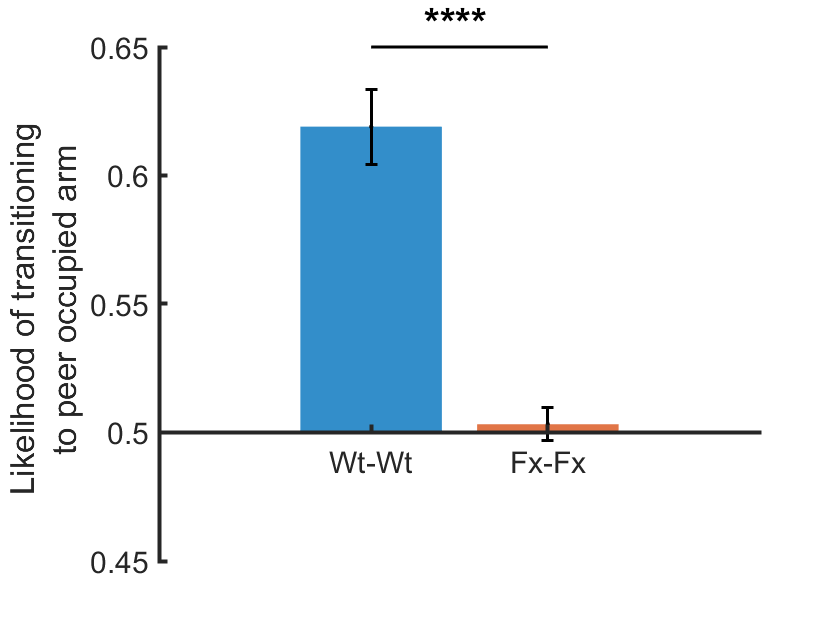

% title(sprintf('FX-FX vs FX-Ctrl p=%.2e, FX-FX vs Ctrl-Ctrl p=%.2e, \n FX-Ctrl vs Ctrl-Ctrl p=%.2e',...
%     a(3), a(2), a(1)));


saveas(gcf,'Mean Likelihood_Cohorts1256_WtvsFx.png');
saveas(gcf,'Mean Likelihood_Cohorts1256_WtvsFx.fig');
saveas(gcf,'Mean Likelihood_Cohorts1256_WtvsFx.eps');